# КУМС. ЛР 3.

Денис Кирбаба R3438

#### 1. Параметры по вариантам

% ob.R = 10 + unifrnd(-1,1);  % сопротивление обмоток двигателя
% ob.L = 0.02 + unifrnd(-0.01,0.01);  % индуктивность обмоток двигателя
% ob.J = 100 + unifrnd(-10,10);  % момент инерции
% ob.Ce = 2;  % константа противо-ЭДС
% ob.Cm = ob.Ce;  % константа по моменту
% ob.kdw = 180/pi;  % коэффициент передачи датчика скорости (пересчет из радиан в градусы)
% save('data.mat','ob')

load("data.mat")

#### 2. Моделирование цифрового И-регулятора

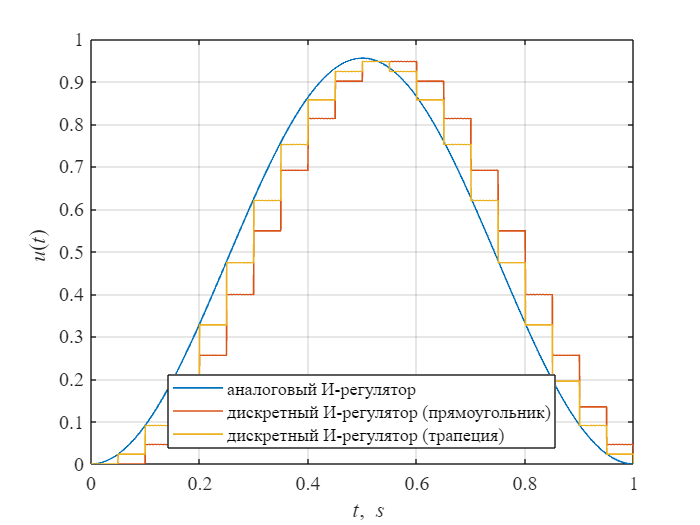

an.Ki = 3;
dsc.Ki = an.Ki;

Tmdl = 1;
To = 0.05;

warning off
SimNew = sim('lab3p2.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.y(:,1);
an.y = SimNew.y(:,2);
dsc1.y = SimNew.y(:,3);
dsc2.y = SimNew.y(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,an.y,'LineWidth',1)
hold on
grid on
plot(t,dsc1.y,'LineWidth',1)
plot(t,dsc2.y,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it u\rm(\itt\rm)')
legend('аналоговый И-регулятор','дискретный И-регулятор (прямоугольник)', ...
    'дискретный И-регулятор (трапеция)','Location','best')

Прямоугольник очень сильно отстает, трапеция поменьше, однако оба дискретных сигнала отстают от синусоиды, то есть нам придется учитывать какое-то запаздывание, которое присутствует в интегральном регуляторе и впоследствии как-то перенастраивать систему.

#### 3. Синтез системы управления с И-регулятором

С И-регулятором мы будем синтезировать систему управления током.

Рассмотрим применение И-регулятора на примере управления контуром тока. Будем производить настрйоку на технический оптимум.

syms Tu L R s

Запишем упрощенную передаточную функцию электрической части электрического привода.

Принято использовать упрощенную модель в случае, когда имеем дело с большим J относительно электрических параметров R,L,Ce (то есть с двигателями с большим ротором). В случае маленьких двигателей (с маленьким ротором) необходимо использовать полную модель, тогда регулятор будет настроен на биномиальный или технический оптимум (будет являться ПИД регулятором).

crl.Wob = 1/(L*s+R);

Передаточная функция разомкнутой системы настроенной на технический оптимум

Tu = L/R;
crl.Wol = 1/(3*Tu*s*(Tu*s+1));

Передаточная функция регулятора

crl.Wreg = crl.Wol/(crl.Wob);
disp(collect(crl.Wreg,s))

$$\frac{R^{2}}{\left(3\,L\right)\,s}$$

Получился интегральный регулятор с коэффициентом R^2/2L = R/2Tu

#### Моделирование работы системы настроенной на технический оптимум

To = 0.1*Tu

crl.Tu = ob.L/ob.R;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

Tmdl = 0.03;
To = 0.1*ob.L/ob.R;

warning off
SimNew = sim('lab3p3a.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab3p3a/crl.Kid
lab3p3a/i trap/Gain2
lab3p3a/i trap/Sum2
lab3p3a/i trap/Gain1
lab3p3a/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p3a/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p3a/A//D C
lab3p3a/Sum1 (alg

warning on

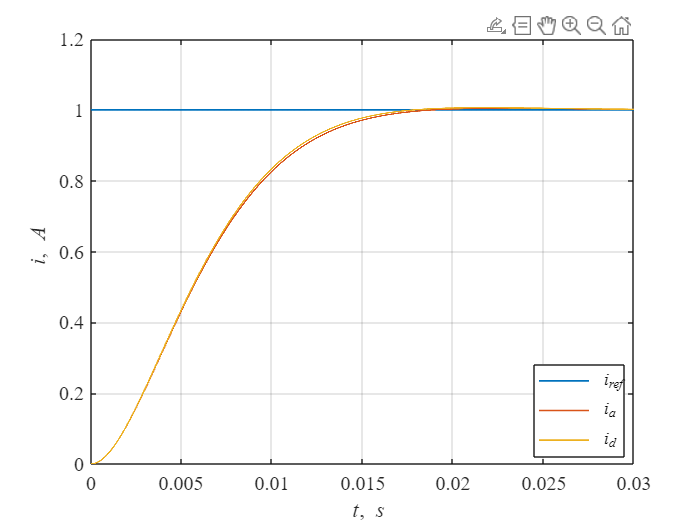

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','Location','best')

В данной ситуации системы близки друг к другу и можно ничего не делать и не пользоваться методом переоборудования.

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 6.4*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.4*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.5%


To = 1*Tu

crl.Tu = ob.L/ob.R;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

Tmdl = 0.045;
To = 1*ob.L/ob.R;

warning off
SimNew = sim('lab3p3a.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab3p3a/crl.Kid
lab3p3a/i trap/Gain2
lab3p3a/i trap/Sum2
lab3p3a/i trap/Gain1
lab3p3a/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p3a/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p3a/A//D C
lab3p3a/Sum1 (alg

warning on

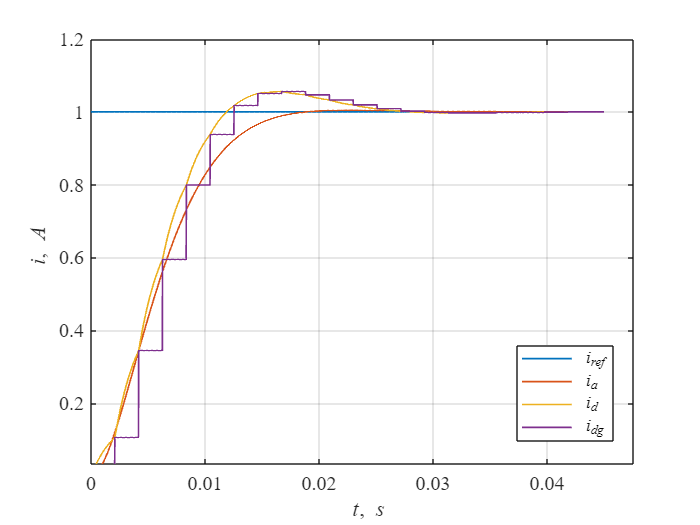

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);
idg = SimNew.ia(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
plot(t,idg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','\it i_dg','Location','best')

Мы наблюдаем затухающие экспоненты которые протекают от точки к точке с расстоянием в значение периода дискретизации, так как на объект мы подаем сигнал, который выходит после эксраполятора нулевого порядка и имеет кусочно-постоянный вид. Поэтому при подаче такого сигнале система реагирует на него переходным процессом на каждом периоде дискретизации.

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 5.1*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 8.5*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 5.6%


#### 4. Синтез системы с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового И-регулятора для случая вычислительной задержки epslison=0

clear Tzap f
To = crl.Tu;
Tmdl = 0.1;
for i = 1:10
    crl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = crl.Tz;
    warning off
    SimNew = sim('lab3p4.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.ia(:,1);
    ia = SimNew.ia(:,3);
    id = SimNew.ia(:,4);
    f(i) = trapz(t,abs(id-ia));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Found algebraic loop containing: 
lab3p4/crl.Kid
lab3p4/i trap/Gain2
lab3p4/i trap/Sum2
lab3p4/i trap/Gain1
lab3p4/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p4/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p4/A//D C
lab3p4/Sum1 (algebraic variable)

Теперь строим график и ищем минимум функционала

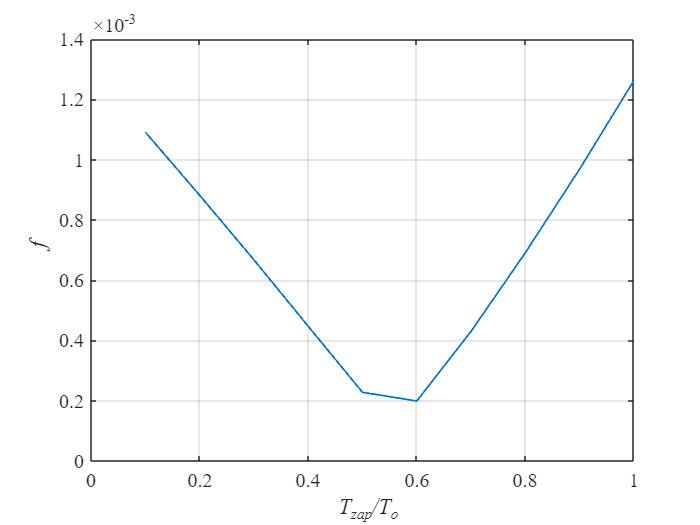

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

To = Te

crl.Tz = 0.6*To;
crl.Tu = ob.L/ob.R + crl.Tz;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

Tmdl = 0.05;
To = ob.L/ob.R;

warning off
SimNew = sim('lab3p4.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab3p4/crl.Kid
lab3p4/i trap/Gain2
lab3p4/i trap/Sum2
lab3p4/i trap/Gain1
lab3p4/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p4/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p4/A//D C
lab3p4/Sum1 (algebraic variable)

warning on

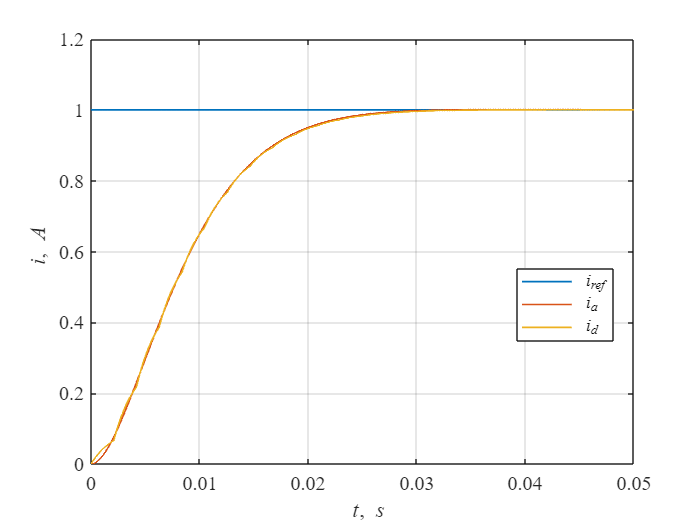

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','Location','best')

Графики почти идеально совпали.

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 6.1*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.0*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


To = 2*Te

crl.Tz = 0.6*To;
crl.Tu = ob.L/ob.R + crl.Tz;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

Tmdl = 0.05;
To = 2*ob.L/ob.R;

warning off
SimNew = sim('lab3p4.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
lab3p4/crl.Kid
lab3p4/i trap/Gain2
lab3p4/i trap/Sum2
lab3p4/i trap/Gain1
lab3p4/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
lab3p4/Electric Drive1/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
lab3p4/A//D C
lab3p4/Sum1 (algebraic variable)

warning on

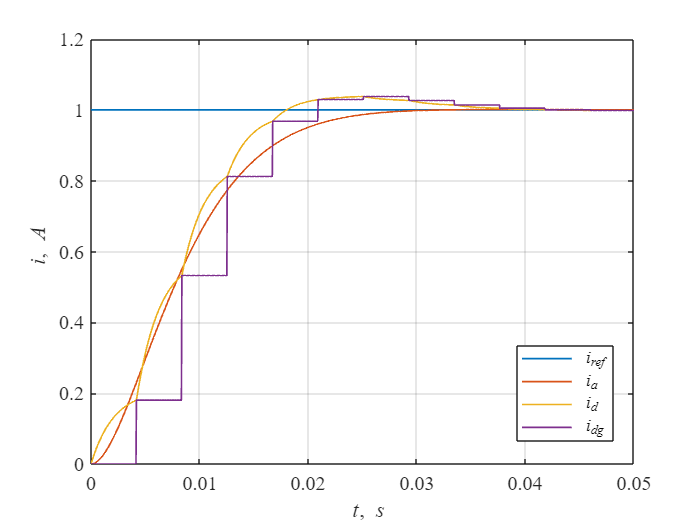

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);
idg = SimNew.ia(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
plot(t,idg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','\it i_dg','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 4.7*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 4.6*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 3.9%


При 2*Te получается что период дискретизации становится существенно больше чем электромагнитная постоянная времени и поэтому ею можно уже пренебрегать и считать объект безинерционным. То есть с дальнейшим увеличением графики переходных процессов будут лучше. Самый худший случай, когда To=Te

#### 5. Синтез системы управления с использованием эквивалентной модели системы, учитывающей динамические свойства цифрового И-регулятора для случая вычислительной задержки e=To

Для реализации вычислительной задержки испольуем блок Unit Delay, который задерживает сигнал на 1 такт дискретизации. На микроконтроллере регулятор рассчитывается не моментально, поэтому появляется вычислительная задержка.

clear Tzap f
To = crl.Tu;
Tmdl = 0.1;
for i = 1:20
    crl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = crl.Tz;
    warning off
    SimNew = sim('lab3p5.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.ia(:,1);
    ia = SimNew.ia(:,3);
    id = SimNew.ia(:,4);
    f(i) = trapz(t,abs(id-ia));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

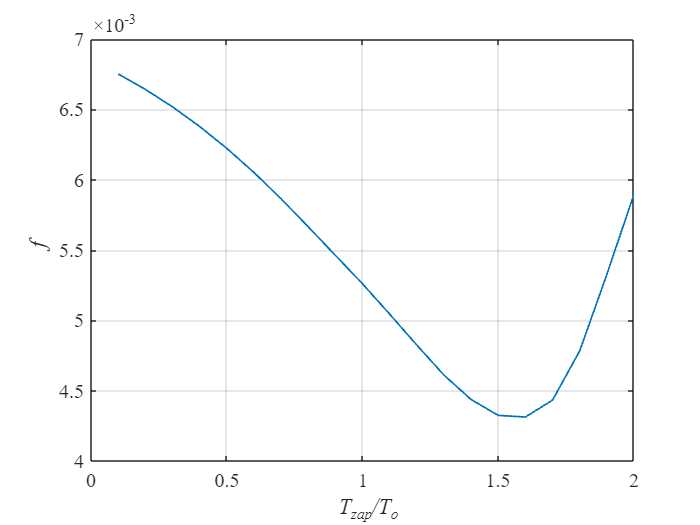

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

To = Te

crl.Tz = 1.6*To;
crl.Tu = ob.L/ob.R + crl.Tz;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

Tmdl = 0.1;
To = ob.L/ob.R;

warning off
SimNew = sim('lab3p5.slx','ReturnWorkspaceOutputs', 'on');
warning on

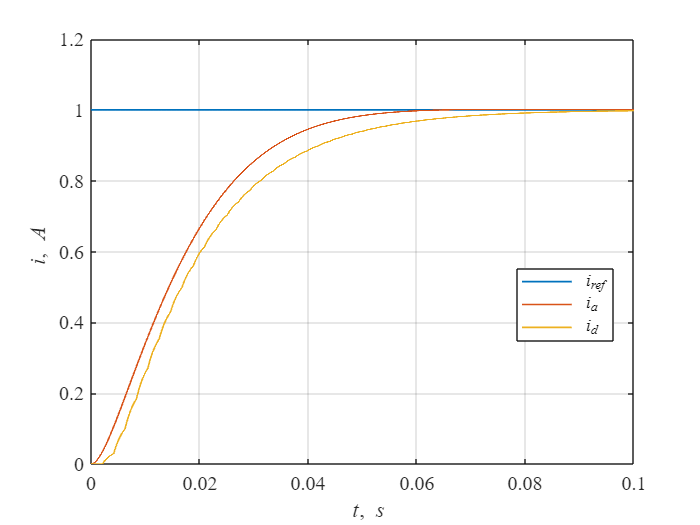

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 7.0*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 7.0*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 0.0%


To = 2*Te

crl.Tz = 1.6*To;
crl.Tu = ob.L/ob.R + crl.Tz;
crl.Kia = ob.R/(3*crl.Tu);
crl.Kid = crl.Kia;

Tmdl = 0.1;
To = 2*ob.L/ob.R;

warning off
SimNew = sim('lab3p5.slx','ReturnWorkspaceOutputs', 'on');
warning on

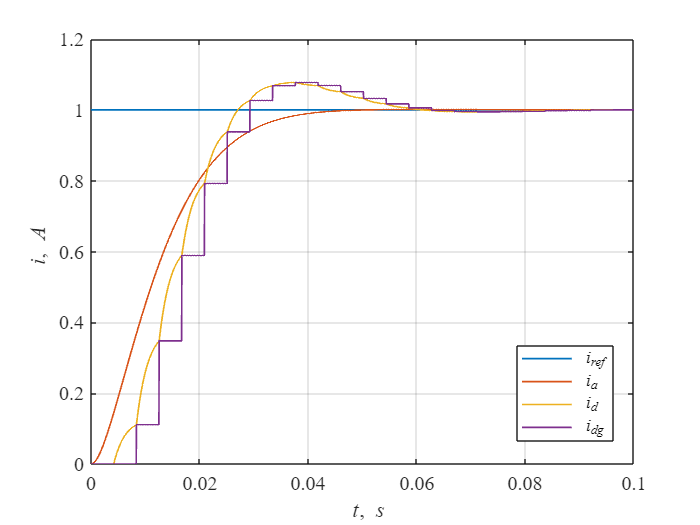

t = SimNew.ia(:,1);
iref = SimNew.ia(:,2);
ia = SimNew.ia(:,3);
id = SimNew.ia(:,4);
idg = SimNew.ia(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,iref,'LineWidth',1)
hold on
grid on
plot(t,ia,'LineWidth',1)
plot(t,id,'LineWidth',1)
plot(t,idg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('\it i_{ref}','\it i_a', '\it i_d','\it i_dg','Location','best')

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = id;
y0 = id(1);
yss = id(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 4.7*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 8.5*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 7.7%
